
%% Principal Component Analysis of EEG data per channel with different filtering methods
% This script performs PCA on EEG data across different conditions and filtering methods
clear;
close all;

%% Set paths based on available drives
if exist('H:\', 'dir')  % Computer 1
    input_base_path = 'H:\My Drive\Data\New Data\EEG epoched';
    output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
elseif exist('G:\', 'dir')  % Computer 2
    input_base_path = 'G:\My Drive\Data\New Data\EEG epoched';
    output_path = 'C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
else
    error('Unknown system: Cannot determine input and output paths.');
end

%% Define analysis parameters
% Define conditions, subjects and channels
conditions = {'BLA', 'BLT', 'P1', 'P2', 'P3'};
subjects = {'BOS2', 'BOS3', 'BOS5', 'BOS6', 'BOS7', 'BOS8', 'BOS9', 'BOS10', ...
    'BOS11', 'BOS12', 'BOS13', 'BOS15', 'BOS16', 'BOS17'};
channels = {'F3', 'C3'};

% Define number of PCs to extract
num_pcs = 32;

% Define filtering parameters
alpha_band = [8 12];  % Alpha band (8-12 Hz)
beta_band = [13 30];  % Beta band (13-30 Hz)

% Create output directory
output_path_perChannel = fullfile(output_path, 'pca_per_channel');
if ~exist(output_path_perChannel, 'dir')
    mkdir(output_path_perChannel);
end

%% Initialize results structures for plotting
% We'll store PC results for each filtering type, condition, and channel
all_results = struct();
for cond_idx = 1:length(conditions)
    condition = conditions{cond_idx};
    all_results.(condition) = struct();
    for ch_idx = 1:length(channels)
        channel = channels{ch_idx};
        all_results.(condition).(channel) = struct();
        all_results.(condition).(channel).unfiltered = [];
        all_results.(condition).(channel).beta = [];
        all_results.(condition).(channel).alpha = [];
        all_results.(condition).(channel).deltaEEG = [];
    end
end

%% Main analysis loop
% Loop over each condition
for cond_idx = 1:length(conditions)
    condition = conditions{cond_idx};
    fprintf('Processing condition: %s\n', condition);
    
    % Set condition-specific paths
    condition_input_path = fullfile(input_base_path, condition);
    condition_output_path = fullfile(output_path_perChannel, condition);
    
    % Create output directory if it doesn't exist
    if ~exist(condition_output_path, 'dir')
        mkdir(condition_output_path);
    end
    
    % Set excel file path for P2 and P3 conditions if needed
    if strcmp(condition, 'P2')
        excel_file_path = fullfile(condition_input_path, 'Indexes for P2.xlsx');
    elseif strcmp(condition, 'P3')
        excel_file_path = fullfile(condition_input_path, 'Indexes for P3.xlsx');
    else
        excel_file_path = '';
    end
    
    % Process each subject's data
    for sub_idx = 1:length(subjects)
        subject = subjects{sub_idx};
        fprintf('  Processing subject: %s\n', subject);
        
        % Load EEG data (modify this to match your file structure)
        eeg_file = fullfile(condition_input_path, [subject '_' condition '.set']);
        
        try
            % Load EEG data
            EEG = pop_loadset(eeg_file);
            fs = EEG.srate;  % Sampling rate
            time_vector = EEG.times / 1000;  % Convert to seconds
            
            % Determine epochs to use based on condition
            if strcmp(condition, 'BLA') || strcmp(condition, 'P1') || strcmp(condition, 'P2') || strcmp(condition, 'P3')
                epoch_trials = 1:2:EEG.trials;  % Odd epochs
            elseif strcmp(condition, 'BLT')
                epoch_trials = 2:2:EEG.trials;  % Even epochs
            else
                error('Condition not recognized. Please specify "BLA" or "BLT".');
            end
            
            num_trials = length(epoch_trials);
            
            % Process each channel
            for ch_idx = 1:length(channels)
                channel = channels{ch_idx};
                fprintf('    Processing channel: %s\n', channel);
                
                % Find channel index
                channel_idx = find(strcmp({EEG.chanlocs.labels}, channel));
                if isempty(channel_idx)
                    warning('Channel %s not found. Skipping.', channel);
                    continue;
                end
                
                % Extract data for this channel across all epochs
                data = EEG.data(channel_idx, :, epoch_trials);  % Channel x Time x Trials
                
                % Initialize arrays to store results
                pc_explained_variance_unfiltered = zeros(num_trials, num_pcs);
                pc_explained_variance_beta = zeros(num_trials, num_pcs);
                pc_explained_variance_alpha = zeros(num_trials, num_pcs);
                pc_explained_variance_deltaEEG = zeros(num_trials, num_pcs);
                
                % Loop through each trial
                for trial_idx = 1:num_trials
                    % Determine time windows based on condition
                    pre_window = [-0.4, 0];  % Pre-stimulus window (-400ms to 0ms)
                    
                    % Set post-stimulus window based on condition and trial
                    if strcmp(condition, 'BLA') || strcmp(condition, 'BLT')
                        post_window = [0, 0.4];  % Post-stimulus window (0ms to +400ms)
                    elseif strcmp(condition, 'P1')
                        post_window = [0, 1.020];  % Post-stimulus window (0ms to +1020ms)
                    elseif strcmp(condition, 'P2')
                        % Read data for both conditions
                        trials_500ms = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 500 ms tactile');
                        trials_2000ms = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 2000 ms tactil');
                        
                        if ismember(epoch_trials(trial_idx), trials_500ms)
                            post_window = [0, 1.020];  % 500ms condition
                        elseif ismember(epoch_trials(trial_idx), trials_2000ms)
                            post_window = [0, 2.400];  % 2000ms condition
                        else
                            continue;  % Skip trials not in either list
                        end
                    elseif strcmp(condition, 'P3')
                        % Read data for both conditions
                        trials_500ms = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 500 ms tactile');
                        trials_missing = readmatrix(excel_file_path, 'Sheet', 'Audio onset with missing tactil');
                        
                        if ismember(epoch_trials(trial_idx), trials_500ms)
                            post_window = [0, 1.020];  % 500ms condition
                        elseif ismember(epoch_trials(trial_idx), trials_missing)
                            post_window = [0, 1.020];  % missing condition
                        else
                            continue;  % Skip trials not in either list
                        end
                    end
                    
                    % Convert time windows to indices
                    pre_idx = find(time_vector >= pre_window(1) & time_vector <= pre_window(2));
                    post_idx = find(time_vector >= post_window(1) & time_vector <= post_window(2));
                    
                    % Combine pre and post indices
                    analysis_idx = [pre_idx, post_idx];
                    
                    % Get trial data
                    trial_data = squeeze(data(:, :, trial_idx));  % 1 x Time
                    
                    % Case 1: Unfiltered signal
                    % PCA on unfiltered signal
                    [~, ~, ~, ~, explained_unfiltered] = pca(trial_data(analysis_idx)');
                    pc_explained_variance_unfiltered(trial_idx, :) = explained_unfiltered(1:min(num_pcs, length(explained_unfiltered)));
                    
                    % Case 2: Beta filtered signal
                    % Apply bandpass filter for beta band
                    beta_signal = bandpass(trial_data, beta_band, fs);
                    [~, ~, ~, ~, explained_beta] = pca(beta_signal(analysis_idx)');
                    pc_explained_variance_beta(trial_idx, :) = explained_beta(1:min(num_pcs, length(explained_beta)));
                    
                    % Case 3: Alpha filtered signal
                    % Apply bandpass filter for alpha band
                    alpha_signal = bandpass(trial_data, alpha_band, fs);
                    [~, ~, ~, ~, explained_alpha] = pca(alpha_signal(analysis_idx)');
                    pc_explained_variance_alpha(trial_idx, :) = explained_alpha(1:min(num_pcs, length(explained_alpha)));
                    
                    % Case 4: Delta EEG (with spatial filtering)
                    % Apply the spatial filtering function to remove surrounding channel influences
                    if size(EEG.data, 1) > 1 % Only if we have multiple channels
                        % Extract all data for this trial to perform spatial filtering
                        all_channels_data = EEG.data(:, :, epoch_trials(trial_idx));
                        
                        % Apply spatial filtering
                        spatially_filtered_data = subtract_surrounding_channels(all_channels_data, EEG.chanlocs);
                        
                        % Get the spatially filtered data for our channel of interest
                        deltaEEG_signal = spatially_filtered_data(channel_idx, :);
                    else
                        % If only one channel is available, we can't perform spatial filtering
                        warning('Cannot perform spatial filtering with only one channel. Using original signal.');
                        deltaEEG_signal = trial_data;
                    end
                    
                    [~, ~, ~, ~, explained_deltaEEG] = pca(deltaEEG_signal(analysis_idx)');
                    pc_explained_variance_deltaEEG(trial_idx, :) = explained_deltaEEG(1:min(num_pcs, length(explained_deltaEEG)));
                end
                
                % Average results across trials
                all_results.(condition).(channel).unfiltered = [all_results.(condition).(channel).unfiltered; nanmean(pc_explained_variance_unfiltered, 1)];
                all_results.(condition).(channel).beta = [all_results.(condition).(channel).beta; nanmean(pc_explained_variance_beta, 1)];
                all_results.(condition).(channel).alpha = [all_results.(condition).(channel).alpha; nanmean(pc_explained_variance_alpha, 1)];
                all_results.(condition).(channel).deltaEEG = [all_results.(condition).(channel).deltaEEG; nanmean(pc_explained_variance_deltaEEG, 1)];
                
                % Save individual channel results
                save(fullfile(condition_output_path, [subject '_' channel '_pca_results.mat']), ...
                    'pc_explained_variance_unfiltered', 'pc_explained_variance_beta', ...
                    'pc_explained_variance_alpha', 'pc_explained_variance_deltaEEG');
            end
            
        catch ME
            warning('Error processing subject %s: %s', subject, ME.message);
            continue;
        end
    end
end

Processing condition: BLA


  Processing subject: BOS2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\BOS2_BLA.set ...


  Processing subject: BOS3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\BOS3_BLA.set ...


  Processing subject: BOS5


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\BOS5_BLA.set ...


  Processing subject: BOS6


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\BOS6_BLA.set ...


  Processing subject: BOS7


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\BOS7_BLA.set ...


  Processing subject: BOS8


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\BOS8_BLA.set ...


  Processing subject: BOS9


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\BOS9_BLA.set ...


  Processing subject: BOS10


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\BOS10_BLA.set ...


  Processing subject: BOS11


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\BOS11_BLA.set ...


  Processing subject: BOS12


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\BOS12_BLA.set ...


  Processing subject: BOS13


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\BOS13_BLA.set ...


  Processing subject: BOS15


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\BOS15_BLA.set ...


  Processing subject: BOS16


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\BOS16_BLA.set ...


  Processing subject: BOS17


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\BOS17_BLA.set ...


Processing condition: BLT


  Processing subject: BOS2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\BOS2_BLT.set ...


  Processing subject: BOS3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\BOS3_BLT.set ...


  Processing subject: BOS5


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\BOS5_BLT.set ...


  Processing subject: BOS6


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\BOS6_BLT.set ...


  Processing subject: BOS7


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\BOS7_BLT.set ...


  Processing subject: BOS8


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\BOS8_BLT.set ...


  Processing subject: BOS9


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\BOS9_BLT.set ...


  Processing subject: BOS10


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\BOS10_BLT.set ...


  Processing subject: BOS11


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\BOS11_BLT.set ...


  Processing subject: BOS12


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\BOS12_BLT.set ...


  Processing subject: BOS13


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\BOS13_BLT.set ...


  Processing subject: BOS15


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\BOS15_BLT.set ...


  Processing subject: BOS16


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\BOS16_BLT.set ...


  Processing subject: BOS17


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\BOS17_BLT.set ...


Processing condition: P1


  Processing subject: BOS2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\BOS2_P1.set ...


  Processing subject: BOS3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\BOS3_P1.set ...


  Processing subject: BOS5


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\BOS5_P1.set ...


  Processing subject: BOS6


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\BOS6_P1.set ...


  Processing subject: BOS7


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\BOS7_P1.set ...


  Processing subject: BOS8


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\BOS8_P1.set ...


  Processing subject: BOS9


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\BOS9_P1.set ...


  Processing subject: BOS10


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\BOS10_P1.set ...


  Processing subject: BOS11


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\BOS11_P1.set ...


  Processing subject: BOS12


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\BOS12_P1.set ...


  Processing subject: BOS13


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\BOS13_P1.set ...


  Processing subject: BOS15


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\BOS15_P1.set ...


  Processing subject: BOS16


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\BOS16_P1.set ...


  Processing subject: BOS17


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\BOS17_P1.set ...


Processing condition: P2


  Processing subject: BOS2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\BOS2_P2.set ...


  Processing subject: BOS3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\BOS3_P2.set ...


  Processing subject: BOS5


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\BOS5_P2.set ...


  Processing subject: BOS6


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\BOS6_P2.set ...


  Processing subject: BOS7


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\BOS7_P2.set ...


  Processing subject: BOS8


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\BOS8_P2.set ...


  Processing subject: BOS9


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\BOS9_P2.set ...


  Processing subject: BOS10


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\BOS10_P2.set ...


  Processing subject: BOS11


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\BOS11_P2.set ...


  Processing subject: BOS12


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\BOS12_P2.set ...


  Processing subject: BOS13


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\BOS13_P2.set ...


  Processing subject: BOS15


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\BOS15_P2.set ...


  Processing subject: BOS16


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\BOS16_P2.set ...


  Processing subject: BOS17


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\BOS17_P2.set ...


Processing condition: P3


  Processing subject: BOS2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\BOS2_P3.set ...


  Processing subject: BOS3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\BOS3_P3.set ...


  Processing subject: BOS5


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\BOS5_P3.set ...


  Processing subject: BOS6


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\BOS6_P3.set ...


  Processing subject: BOS7


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\BOS7_P3.set ...


  Processing subject: BOS8


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\BOS8_P3.set ...


  Processing subject: BOS9


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\BOS9_P3.set ...


  Processing subject: BOS10


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\BOS10_P3.set ...


  Processing subject: BOS11


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\BOS11_P3.set ...


  Processing subject: BOS12


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\BOS12_P3.set ...


  Processing subject: BOS13


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\BOS13_P3.set ...


  Processing subject: BOS15


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\BOS15_P3.set ...


  Processing subject: BOS16


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\BOS16_P3.set ...


  Processing subject: BOS17


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\BOS17_P3.set ...


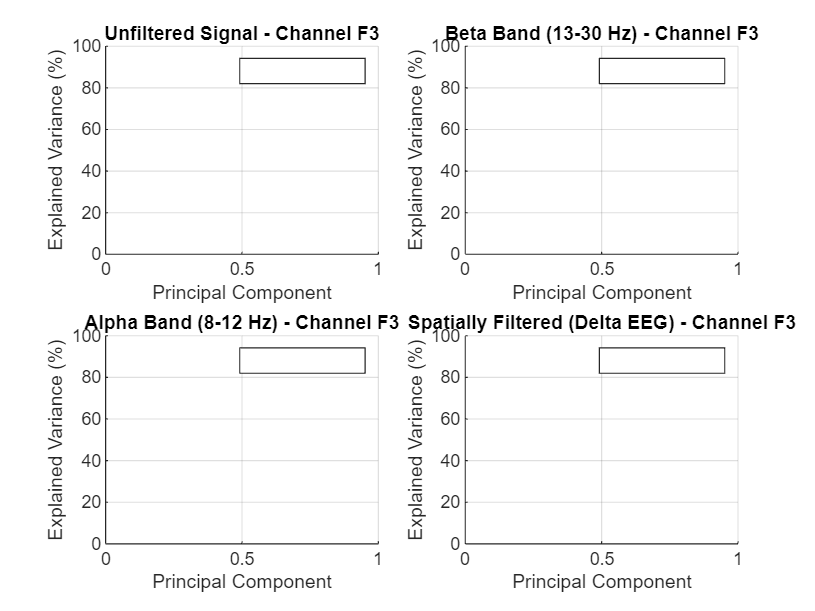

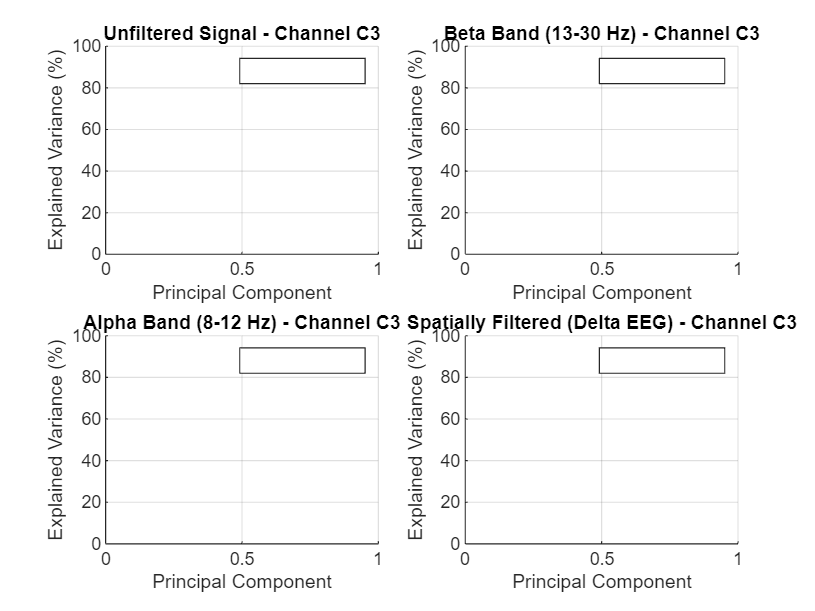

%% Generate final plots
% For each channel, create a figure with subplots for each filtering method
% Each subplot will contain results for all conditions

filter_types = {'unfiltered', 'beta', 'alpha', 'deltaEEG'};
filter_titles = {'Unfiltered Signal', 'Beta Band (13-30 Hz)', 'Alpha Band (8-12 Hz)', 'Spatially Filtered (Delta EEG)'};

for ch_idx = 1:length(channels)
    channel = channels{ch_idx};
    
    figure('Name', ['PCA Results for Channel ' channel], 'Position', [100, 100, 1200, 900]);
    
    for f_idx = 1:length(filter_types)
        filter_type = filter_types{f_idx};
        
        % Create subplot
        subplot(2, 2, f_idx);
        hold on;
        
        % Plot each condition
        for cond_idx = 1:length(conditions)
            condition = conditions{cond_idx};
            
            % Get mean explained variance across subjects
            mean_explained = nanmean(all_results.(condition).(channel).(filter_type), 1);
            
            % Plot explained variance for each PC
            plot(1:length(mean_explained), mean_explained, 'LineWidth', 2, 'DisplayName', condition);
        end
        
        % Add labels and title
        xlabel('Principal Component');
        ylabel('Explained Variance (%)');
        title([filter_titles{f_idx} ' - Channel ' channel]);
        legend('Location', 'NorthEast');
        grid on;
        
        % Add cumulative variance plot
        for cond_idx = 1:length(conditions)
            condition = conditions{cond_idx};
            mean_explained = nanmean(all_results.(condition).(channel).(filter_type), 1);
            cumulative = cumsum(mean_explained);
            
           % Get color from color order
            colorOrder = get(gca, 'ColorOrder');
            lineColor = colorOrder(mod(cond_idx-1, size(colorOrder, 1))+1, :);
            
            % Plot cumulative variance with dashed line
            plot(1:length(cumulative), cumulative, '--', 'LineWidth', 1, 'Color', lineColor);
        end
        
        % Set y-axis limits
        ylim([0, 100]);
        
        hold off;
    end
    
    % Save the figure
    saveas(gcf, fullfile(output_path_perChannel, ['PCA_Results_Channel_' channel '.fig']));
    saveas(gcf, fullfile(output_path_perChannel, ['PCA_Results_Channel_' channel '.png']));
end


fprintf('Analysis complete! Results saved to: %s\n', output_path_perChannel);

Analysis complete! Results saved to: C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results\pca_per_channel


%% Helper function for spatial filtering (Delta EEG)
function filtered_data = subtract_surrounding_channels(data, channel_locations)
    % Subtracts the mean of surrounding channels from each channel
    % 
    % Inputs:
    %   data: EEG data matrix (channels x time x trials)
    %   channel_locations: EEG.chanlocs structure containing channel coordinates
    %
    % Output:
    %   filtered_data: Data with surrounding channel mean subtracted
    
    num_channels = size(data, 1);
    num_timepoints = size(data, 2);
    num_trials = size(data, 3);
    filtered_data = zeros(size(data));
    
    % Extract coordinates for all channels
    if isfield(channel_locations, 'X') && isfield(channel_locations, 'Y') && isfield(channel_locations, 'Z')
        coords = [[channel_locations.X]', [channel_locations.Y]', [channel_locations.Z]'];
    else
        error('Channel locations must contain X, Y, and Z coordinates');
    end
    
    % Calculate Euclidean distances between all channels
    distances = zeros(num_channels, num_channels);
    for i = 1:num_channels
        for j = 1:num_channels
            distances(i,j) = sqrt(sum((coords(i,:) - coords(j,:)).^2));
        end
    end
    
    % Define surrounding channels for each channel
    % You can adjust the threshold to define what "surrounding" means
    threshold = mean(distances(:)) * 0.5; % Adjust this multiplier as needed
    
    for ch = 1:num_channels
        % Find surrounding channels (channels within threshold distance)
        surrounding_idx = find(distances(ch,:) > 0 & distances(ch,:) <= threshold);
        
        if isempty(surrounding_idx)
            warning(['No surrounding channels found for channel ', num2str(ch), '. Keeping original signal.']);
            filtered_data(ch,:,:) = data(ch,:,:);
            continue;
        end
        
        % Calculate mean of surrounding channels
        surrounding_mean = mean(data(surrounding_idx,:,:), 1);
        
        % Subtract surrounding mean from the channel
        filtered_data(ch,:,:) = data(ch,:,:) - surrounding_mean;
    end
end